addpath('Kinematics')
addpath('Kinetics')

supressed_print= evalc('run Linearize_EOMs.mlx'); %Run the script to generate the equations of motion for the Ball and Plate in terms of the u-joint torques

clear supressed_print

sympref('FloatingPoint',true);

# Linear Trajectory Tracking Controller

Here, we will...

## Reformulate the System as Two Decoupled, Fourth Order, Single Input Systems

A system with state vector $\tilde{x}_{1} $:


$$\tilde{x}_{1} = [x  ~\beta ~\dot{x}~\dot{\beta}]^T

$$


And state equation:


$$\dot{\tilde{x}}_{1} = A_{1} \tilde{x}_{1} + B_{1}\tilde{u}_{1}$$


A1 = A_uc(1:4,1:4)

$$A1 = \left[\begin{array}{cccc} 0 & 1 & 0 & 0\\ -5.2170 & 0 & 4.0111 & 0\\ 0 & 0 & 0 & 1\\ 112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$

B1 = B_uc(1:4,1)

$$B1 = \left[\begin{array}{c} 0\\ -17.7268\\ 0\\ 383.5785 \end{array}\right]$$

C1 = eye(4)

C1 =      1     0     0     0
     0     1     0     0
     0     0     1     0
     0     0     0     1


D1 = [0;0;0;0]

D1 =      0
     0
     0
     0


And another system with state vector $\tilde{x}_{2} $:


$$\tilde{x}_{2} = [y~\gamma~\dot{y}~\dot{\gamma}]^T$$


And state equation:


$$\dot{\tilde{x}}_{2} = A_{2} \tilde{x}_{2} + B_{2}\tilde{u}_{2}$$


A2 = A_uc(5:8,5:8)

$$A2 = \left[\begin{array}{cccc} 0 & 1 & 0 & 0\\ -5.2170 & 0 & -4.0111 & 0\\ 0 & 0 & 0 & 1\\ -112.8871 & 0 & 64.8295 & 0 \end{array}\right]$$

B2 = B_uc(5:8,2)

$$B2 = \left[\begin{array}{c} 0\\ 17.7268\\ 0\\ 383.5785 \end{array}\right]$$

C2 = C1;
D2 = D1;

## Control Canonical Form of Each System

### Characteristic Equations to Check Canonical Forms

syms s;
Char_Eqn1 = det(s*eye(4) - A1)

$$Char\_Eqn1 = s^{4}-59.6125\,s^{2}-791.0163$$

Char_Eqn2 = det(s*eye(4) - A2)

$$Char\_Eqn2 = s^{4}-59.6125\,s^{2}-791.0163$$

### Get Coefficients

CharEqnCoeffs = sym(coeffs(Char_Eqn1,'All'))

$$CharEqnCoeffs = \left[\begin{array}{ccccc} 1 & 0 & -59.6125 & 0 & -791.0163 \end{array}\right]$$

### Get Observable Canonical Form Transformation

Non controllable canonical form function available in MATLAB but its just the transpose of the observable canonical form.

P1 = sym(ctrb(A1,B1)); %Controllability matrix for original system
A1p = [ zeros(3,1), eye(3)
        -CharEqnCoeffs(5),-CharEqnCoeffs(4),-CharEqnCoeffs(3),-CharEqnCoeffs(2)] %A matrix in controllable canonical form

$$A1p = \left[\begin{array}{cccc} 0 & 1 & 0 & 0\\ 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 1\\ 791.0163 & 0 & 59.6125 & 0 \end{array}\right]$$

B1p = sym([0;0;0;1])

$$B1p = \left[\begin{array}{c} 0\\ 0\\ 0\\ 1 \end{array}\right]$$

P1p = sym(ctrb(A1p, B1p));
T = P1p*inv(P1)

$$T = \left[\begin{array}{cccc} 3.7205e-04 & 0 & 1.7194e-05 & 0\\ 0 & 3.7205e-04 & 0 & 1.7194e-05\\ 7.1127e-08 & 0 & 0.0026 & 0\\ 0 & 7.1127e-08 & 0 & 0.0026 \end{array}\right]$$

det(inv(T))*det(T) %Checking that T^-1*T has no scaling effects

$$ans = 1$$

Bottom row solving for $T_\beta$ - Solve for $T_\beta$ that drives the trajectory. This should be consistent with an arbitrary trajectory in $x$ so long as $\beta$ and $\ddot{\beta}$ are consistent with the trajectory. 

syms x_dot_prime_4 x_prime_1 x_prime_2 x_prime_3 x_prime_4

%Canonical form variables
x_dot_prime_4 - A1p(4,:)*[x_prime_1 x_prime_2 x_prime_3 x_prime_4].' == T_beta

$$ans = {{\dot{x}}^{\prime }}_{4}-791.0163\,{x^{\prime }}_{1}-59.6125\,{x^{\prime }}_{3}=T_{\beta }$$

%State variables
x1_prime = T\stateVec1_dot;
OL_torque_eqn = x1_prime(4) - A1p(4,:)*(T\stateVec1) == T_beta

$$OL\_torque\_eqn = -2.1261e+06\,x-0.0733\,\ddot{x}+383.5785\,\ddot{\beta }-8.8439e+03\,\beta =T_{\beta }$$

OL_Traj_Gain = double(equationsToMatrix(OL_torque_eqn, [x,x_ddot,beta,beta_ddot]))

OL_Traj_Gain = 	1.0e+06 *

   -2.1261   -0.0000   -0.0088    0.0004


### Check the Similarity Transform


$$A = T^{-1}A'T$$


A1_check = T\A1p*T

$$A1\_check = \left[\begin{array}{cccc} 0 & 1 & 0 & 0\\ -5.2168 & 0 & 4.0112 & 0\\ 0 & 0 & 0 & 1\\ 112.8868 & 0 & 64.8293 & 0 \end{array}\right]$$

## Trajectory Generation

We specify a trajectory in x and y variables as functions of time and compute $\dot{x},~ \ddot{x}, ~\dot{y}, ~ and~ \ddot{y}$, from this trajectory. This is the end of the trajectory we care about though - the rest should be chosen only such that they are consistent with the physical system. 

### Linear System 1 Equations (Symvars)

sys1_eqns = stateVec1_dot == A1*stateVec1 + B1*T_beta

$$sys1\_eqns = \left[\begin{array}{c} \dot{x}=\dot{x}\\ \ddot{x}=-5.2170\,x+4.0111\,\beta -17.7268\,T_{\beta }\\ \dot{\beta }=\dot{\beta }\\ \ddot{\beta }=112.8871\,x+64.8295\,\beta +383.5785\,T_{\beta } \end{array}\right]$$

Eliminate $T_\beta$ and Determine $\ddot{\beta}$ and $\beta$ in Terms of the Desired Trajectory. This produces the a trajectory in the remaining variables that is consistent with the desired trajectory in $x$. 

beta_consistancy_ode = isolate(0 == eliminate(sys1_eqns, T_beta), beta_ddot)

$$beta\_consistancy\_ode = \ddot{\beta }=-21.6383\,\ddot{x}+151.6229\,\beta$$

### Simulate Generated Trajectory

A1_sim = double(A1);
B1_sim = double(B1);
t_sim = 10;

%Choosing an arbitrary initial beta and beta_dot for the trajectory in x (not unique
%variables in the x trajectory)
beta_bar0 = .25;
beta_bar_dot0 = .3;

r_sim = 50; % radius of circular trajectory [mm]
omega_sim = .2; %angular frequency of circular trajectory [mm]

Try to solve for $\beta(t)$ explicitly

syms omega r
ode_explicit(t) = subs(beta_consistancy_ode, x_ddot, -r*omega^2*cos(omega*t))

$$ode\_explicit(t) = \ddot{\beta }=151.6229\,\beta +21.6383\,\omega^{2}\,r\,\cos\left(\omega \,t\right)$$

ode_explicit(t) = subs(ode_explicit, symVarVec, symFunVec)

$$ode\_explicit(t) = \frac{\partial^{2}}{\partial t^{2}}\hat{\beta }\left(t\right)=151.6229\,\hat{\beta }\left(t\right)+21.6383\,\omega^{2}\,r\,\cos\left(\omega \,t\right)$$

analytical_sol(t,omega,r) = dsolve(ode_explicit)

$$analytical\_sol(t, omega, r) = C_{1}\,{\mathrm{e}}^{-12.3135\,t}+C_{2}\,{\mathrm{e}}^{12.3135\,t}-\frac{0.8786\,\omega^{2}\,r\,\left(12.3135\,\cos\left(\omega \,t\right)+\omega \,\sin\left(\omega \,t\right)\right)}{\omega^{2}+151.6229}-\frac{0.8786\,\omega^{2}\,r\,\left(12.3135\,\cos\left(\omega \,t\right)-\omega \,\sin\left(\omega \,t\right)\right)}{\omega^{2}+151.6229}$$

analytical_sol(0,r_sim,omega_sim)

$$ans = C_{1}+C_{2}-4.0802$$

diff_soln(t) = diff(analytical_sol,t);
diff_soln(0)

$$ans = -12.3135\,C_{1}+12.3135\,C_{2}$$

Run Numerical Simulation of System:

out = sim('Generated_Trajectory_Linear_System')

out =   Simulink.SimulationOutput:

                   tout: [125x1 double] 
                     x1: [125x4 double] 
                 x1_bar: [125x4 double] 

     SimulationMetadata: [1x1 Simulink.SimulationMetadata] 
           ErrorMessage: [0x0 char] 


### Plot to Verify

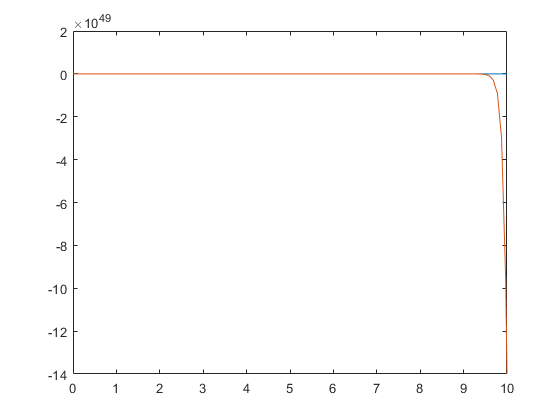

figure
plot(out.tout, out.x1_bar(:,1),out.tout, out.x1(:,1))